# Live Structure from motion

clear;
dataset_name="B_1_2_20";
load('DEMs/uavision_DEM_120'); % DEM

## Load images

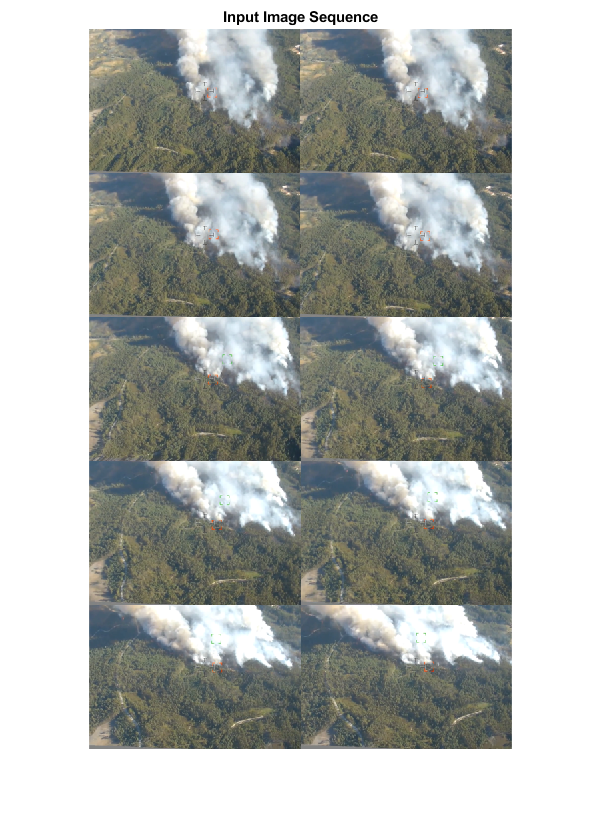

%dataset_name='B_1_2_10';%'A_30_1_35';
imageDir = strcat('Datasets/',dataset_name);
imds = imageDatastore(imageDir);

% Display the images.
figure;
montage(imds.Files, 'Size', [5, 2]);

% Convert the images to grayscale.
images = cell(1, numel(imds.Files));
for i = 1:numel(imds.Files)
    I = readimage(imds, i);
    images{i} = rgb2gray(I);
end
I=images{1};
title('Input Image Sequence');

## Load Camera parameters

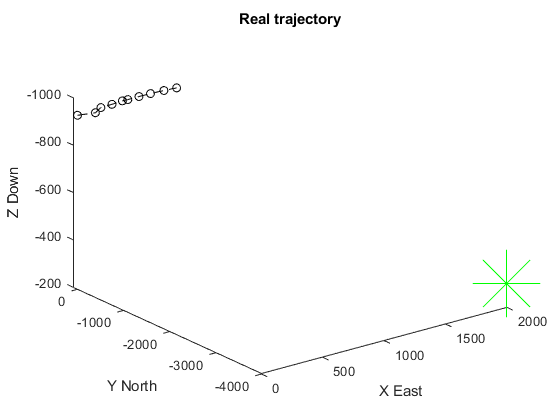

% Load intrinsics and extrinsics
load('intrinsics/intrinsics');
load(strcat('Datasets/',dataset_name,'/extrinsics'));

% get translation parameter (in N-E-D)
origin = [gps(1,1), gps(1,2), altitude(1)];
[cam_x,cam_y] = latlon2local(gps(:,1),gps(:,2),altitude,origin);
cam_z=-altitude;
cam_pos=[cam_x cam_y cam_z];

% camera orientation: roll pitch yaw
pitch=deg2rad(90+pitch);
roll=zeros(size(pitch));
yaw=deg2rad(90-heading);

% plot trajectory and target
figure;plot3(cam_x,cam_y,cam_z,'k--o');
title("Real trajectory");
xlabel(" X East");
ylabel("Y North");
zlabel("Z Down")
set(gca, 'ZDir','reverse');
hold on;
plot3(target(1),target(2),-300,'g*','MarkerSize',50);

## Select detector

detector="ORB";
features_per_image =5000;
SURF_octave_number = 8;

% SURF
if detector=="SURF"
    border = 50;
    %[x y width height]
    roi = [border, border, size(I, 2)- 2*border, size(I, 1)- 2*border]; 
    
    
    prevPoints   = detectSURFFeatures(I, 'NumOctaves', SURF_octave_number, 'ROI', roi);
    prevFeatures = extractFeatures(I, prevPoints, 'Upright', true);
end

% ORB
if detector=="ORB"
    prevPoints=selectStrongest(detectORBFeatures(I),features_per_image);    
    prevFeatures = extractFeatures(I, prevPoints);
end

% KAZE
if detector=="KAZE"
    prevPoints   = selectStrongest(detectKAZEFeatures(I),features_per_image);
    prevFeatures = extractFeatures(I, currPoints, 'Upright', true);
end

% Extract features and add them to the imageview set object
%, 'Upright', true);

%% Create an empty imageviewset object to manage the data associated with each
% view.
% 
vSet = imageviewset;
viewId = 1;
vSet = addView(vSet, viewId, rigid3d(angle2dcm( yaw(1), pitch(1), roll(1),'ZYZ'),cam_pos(1,:)), ...
    'Points', prevPoints);

## Visualize features detected

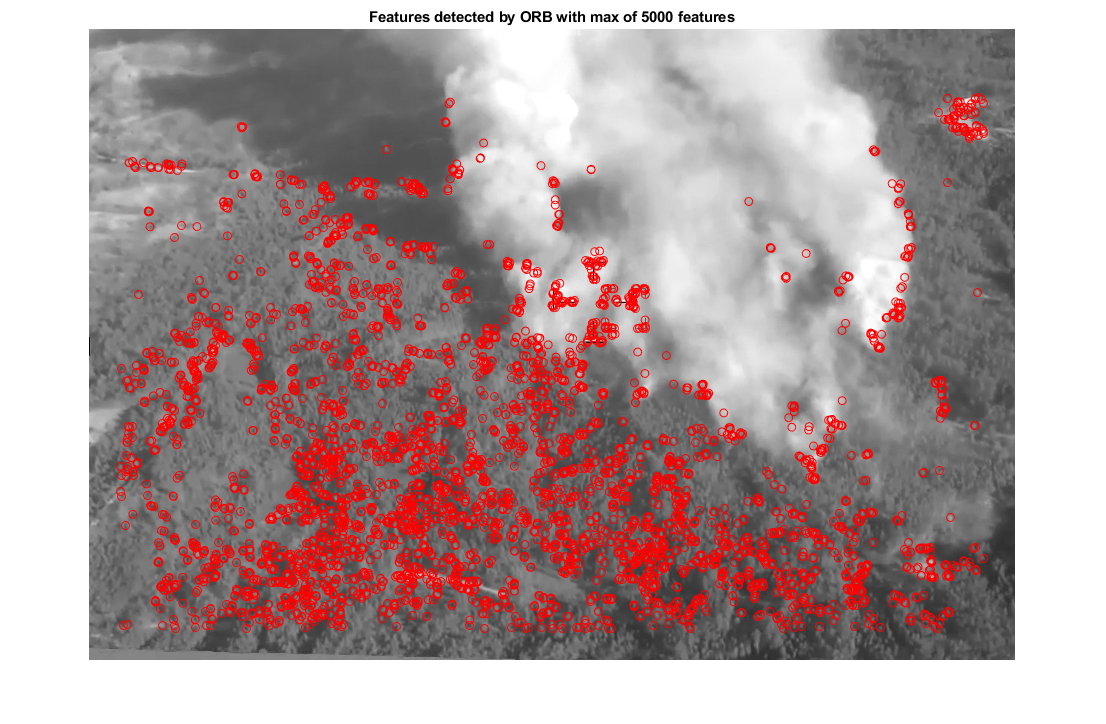

figure(); imshow(I);hold on;
scatter(prevPoints.Location(:,1),prevPoints.Location(:,2),'r');
title(strcat("Features detected by ",detector, " with max of ",int2str(features_per_image), ' features'));

## Process the next views


i=4;
error_on_off=false;
reprojection_error_threshold=100;
outlier_detection=false;
mask_1=false;
mask_2=false;
mask_3=mask_2;
mask_4=false;
input_mask=[mask_1 mask_2 mask_3 mask_4 0];


I = images{i};
    
% Detect features.
if detector=="SURF"
    currPoints   = detectSURFFeatures(I, 'NumOctaves', SURF_octave_number, 'ROI', roi);
    currFeatures = extractFeatures(I, currPoints, 'Upright', true);
end

if detector=="ORB"
    currPoints = selectStrongest(detectORBFeatures(I),features_per_image);
    currFeatures = extractFeatures(I, currPoints);
end

if detector=="KAZE"
    currPoints   = selectStrongest(detectKAZEFeatures(I),features_per_image);
    currFeatures = extractFeatures(I, currPoints, 'Upright', true);
    
end

% Extract and match features


indexPairs   = matchFeatures(prevFeatures, currFeatures,'MaxRatio', .7, 'Unique',  true);

% Select matched points.
matchedPoints1 = prevPoints(indexPairs(:, 1));
matchedPoints2 = currPoints(indexPairs(:, 2));

% Add the current view to the view set.
vSet = addView(vSet, i, rigid3d(angle2dcm( yaw(i), pitch(i), roll(i),'ZYZ' ), ...
    cam_pos(i,:)), 'Points', currPoints);

% Store the point matches between the previous and the current views.
vSet = addConnection(vSet, i-1, i, 'Matches', indexPairs(:,:));

% Find point tracks across all views.
tracks = findTracks(vSet);

% Get the table containing camera poses for all views.
camPoses = poses(vSet);

% Triangulate initial locations for the 3-D world points
% And then  remove outliers
xyzPoints = triangulateMultiview(tracks, camPoses, intrinsics);

% remove outliers from xyzPoints
% first remove points behind the camera

% then call a function to remove the rest of the outliers
if outlier_detection== true
    [xyzPoints,tracks]=remove_outliers(...
        xyzPoints,tracks,cam_pos,[yaw(i) pitch(i) roll(i)],input_mask);
end


% Refine the 3-D world points and camera poses.
[xyzPoints,reprojectionErrors] = bundleAdjustmentStructure(xyzPoints, ...
    tracks, camPoses, intrinsics);

% Remove points with high reprojection error
if error_on_off== true
    good_mask= reprojectionErrors<reprojection_error_threshold;
    xyzPoints=xyzPoints(good_mask,:);
    tracks=tracks(good_mask);
    reprojectionErrors=reprojectionErrors(good_mask);
end



prevFeatures = currFeatures;
prevPoints   = currPoints;



## Matched points between images

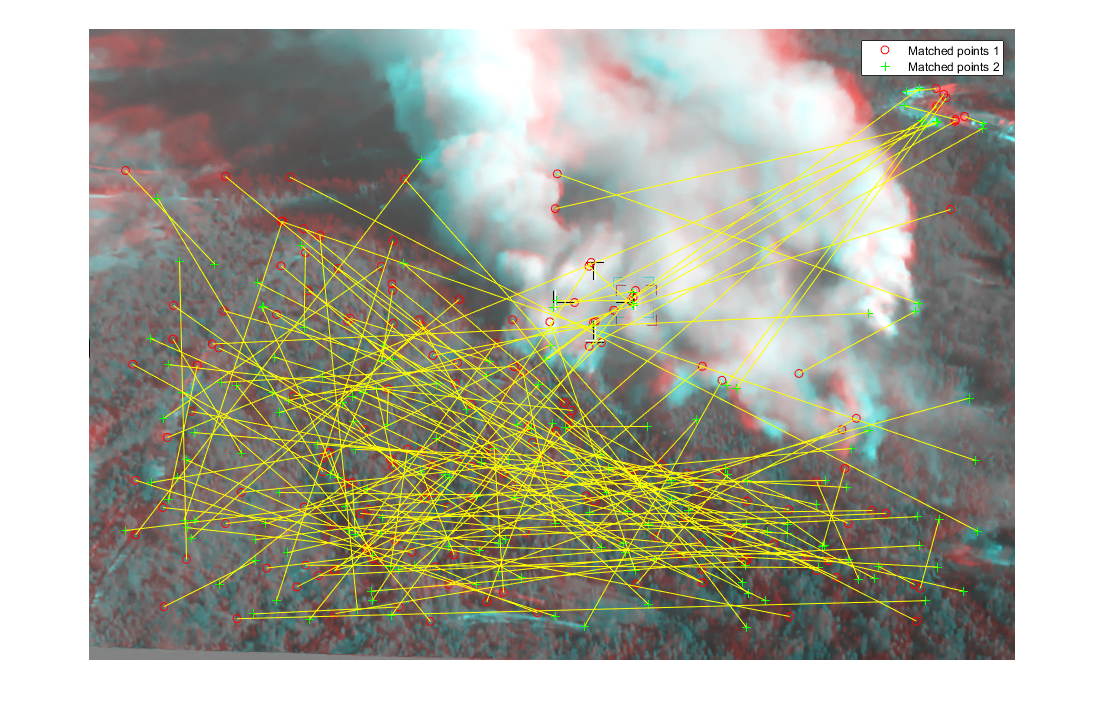

% matched points
figure; ax = axes; showMatchedFeatures(images{i-1},I,matchedPoints1,matchedPoints2,'Parent',ax);
legend(ax,'Matched points 1','Matched points 2');

## Reprojection error

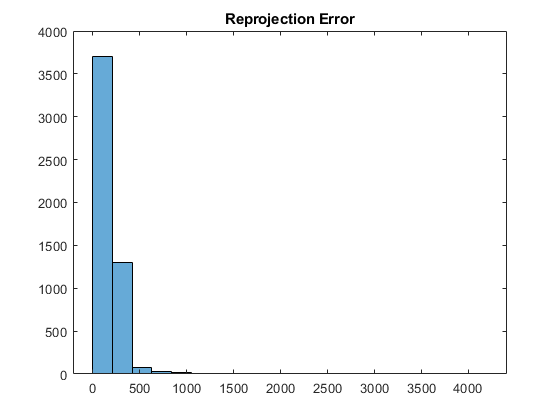

figure;histogram(reprojectionErrors,20);title('Reprojection Error');

## 3D points

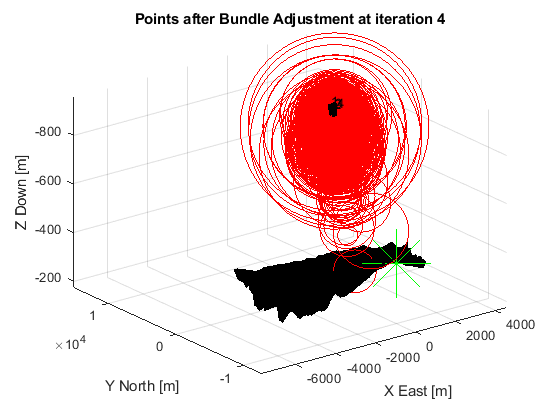



figure;
scatter3(xyzPoints(:,1),xyzPoints(:,2),xyzPoints(:,3),reprojectionErrors*5,'r');
hold on; 
plotCamera(camPoses, 'Size', 20,'Color','k');
res=30;%m/square
DEM_X=res*size(small_A,1)/-2:res:res*size(small_A,1)/2; DEM_X=DEM_X(1:size(small_A,1));
DEM_Y=res*size(small_A,2)/-2:res:res*size(small_A,2)/2; DEM_Y=DEM_Y(1:size(small_A,2));
hold on;
surf(DEM_X,DEM_Y,-small_A);
hold on;
plot3(target(1),target(2),-300,'g*','MarkerSize',50);
title(strcat("Points after Bundle Adjustment at iteration ",int2str(i)));
set(gca, 'ZDir','reverse');
xlabel(" X East [m]");
ylabel("Y North [m]");
zlabel("Z Down [m]");

xlim([ min([xyzPoints(:,1)' cam_x']) , max([xyzPoints(:,1)' cam_x']) ]);
ylim([ min([xyzPoints(:,2)' cam_y']) , max([xyzPoints(:,2)' cam_y']) ]);
zlim([cam_z(1)-20,-min(small_A,[],'all')]);

## Points   detected in new image

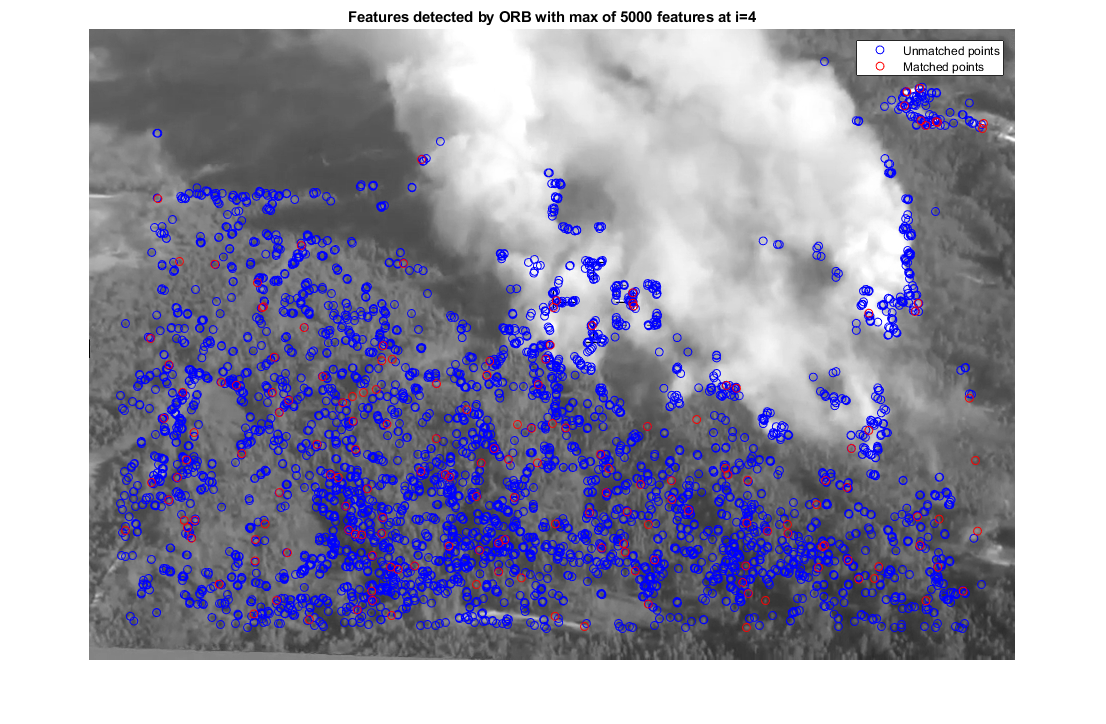

figure(); imshow(I);hold on;
scatter(currPoints.Location(:,1),currPoints.Location(:,2),'b');
hold on;
scatter(matchedPoints2.Location(:,1),matchedPoints2.Location(:,2),'r');
title(strcat("Features detected by ",detector, " with max of ",int2str(features_per_image), ' features at i=',int2str(i)));
legend('Unmatched points','Matched points')